Detector = load("DetectorARMChallenge2.mat").Detector1;
colorImage = imread("C:\Users\RoboIME\Desktop\fotos\10calib.png");
depthImage = imread("C:\Users\RoboIME\Desktop\fotos\10_d.png");

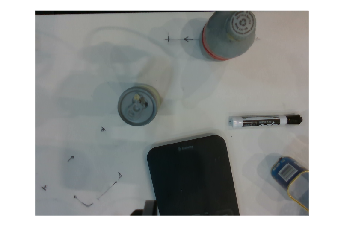

        % Capturar imagem
        % [colorImage, depthImage] = realSense.step;
        % depthImage = depthImage(:,:,3);
        % colorImage = imresize(colorImage,[480,640]);
        % depthImage = imresize(depthImage,[480,640]);
        imshow(colorImage);

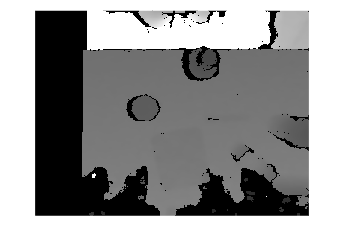

        imshow(depthImage);

Pontos iniciais: 307200 | Após filtro: 275100
Pontos iniciais: 16284 | Após filtro: 7921
Pontos iniciais: 9999 | Após filtro: 6497
Pontos iniciais: 6230 | Após filtro: 5101
Pontos iniciais: 41800 | Após filtro: 38603
Pontos iniciais: 11397 | Após filtro: 8280
Pontos iniciais: 16284 | Após filtro: 7921
Pontos iniciais: 9999 | Após filtro: 6497
Pontos iniciais: 6230 | Após filtro: 5101


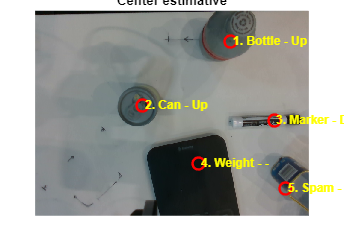


idxvarado =

  0×1 empty double column vector



sts = 5×1 categorical array
     Up 
     Up 
     Down 
     - 
     - 


labels = 5×1 categorical array
     Bottle 
     Can 
     Marker 
     Weight 
     Spam 


scores = 5×1 single column vector
    0.7403
    0.8986
    0.8747
    0.8892
    0.9553


        
        pack = cell(1,3);
        pack{1} = Detector;
        pack{2} = colorImage;
        pack{3} = depthImage;
        
        [~,~,objSem,~] = PcGenRSD435(pack);
        
        [~,idxvarado,sts,labels,scores] = ARMVision(colorImage,depthImage,Detector,0.5)

        
        dzInicial = 0.05;
        minPontosInicial = 3000;
        ptobjeto = objSem{i};

Index exceeds the number of array elements. Index must not exceed 5.

        
        [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);


     Can 



h_objeto =  0.108 metros
em pé


em pé


     0



     Bottle 



h_objeto =  0.075 metros
deitado


Ângulo theta dominante: 3.57 graus


rot = single
0.0623

deitado


    0.0623



     Marker 



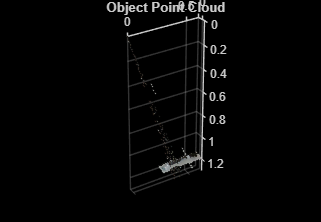

h_objeto =  -0.001 metros
deitado


Ângulo theta dominante: 0.11 graus


rot = single
0.0020

deitado


    0.0020



for k = 1:3
    UR5 = 0;
    label = objLabel(k);
    disp(label);

    dzInicial = 0.05;
    minPontosInicial = 3000;

    ptobjeto = ptobj{k};
    pcshow(ptobjeto,'VerticalAxis','Z','VerticalAxisDir','Down');
    title("Object Point Cloud");

    % Lata 1
    if label == "Can"
        [z1, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
        estado = calcular_estado(z1, label,z2);
        if estado == "em pé"
            rot = 0;
        elseif estado == "deitado"
            rot = Calcular_rot(ptselecao,UR5)
        end
        disp(estado);
        disp(rot);

     % garrafa 1   
    elseif label == "Bottle"
    [z1, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
        estado = calcular_estado(z1, label,z2);
        if estado == "em pé"
            rot = 0;
        elseif estado == "deitado"
            rot = Calcular_rot(ptselecao,UR5)
        end
        disp(estado);
        disp(rot);

    % Marker
    elseif label == "Marker"
        [z1, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
        estado = calcular_estado(z1, label,z2);
        if estado == "em pé"
            rot = 0;
        elseif estado == "deitado"
            rot = Calcular_rot(ptselecao,UR5)
        end
        disp(estado);
        disp(rot);
    end
end